%% initial settings
clearvars;
%%
%fish_data_analysis;
l = 2; % [200, 400, 600]
data_import_MC;
data_import_MIP;
fish_data_analysis;
Fish_analysis;

### Figure 2

% time series log(PHI)
% Figure 2a
ind = 2 % ind = [1, 2, 3, 4, 5, 6, 7]

ind = 2

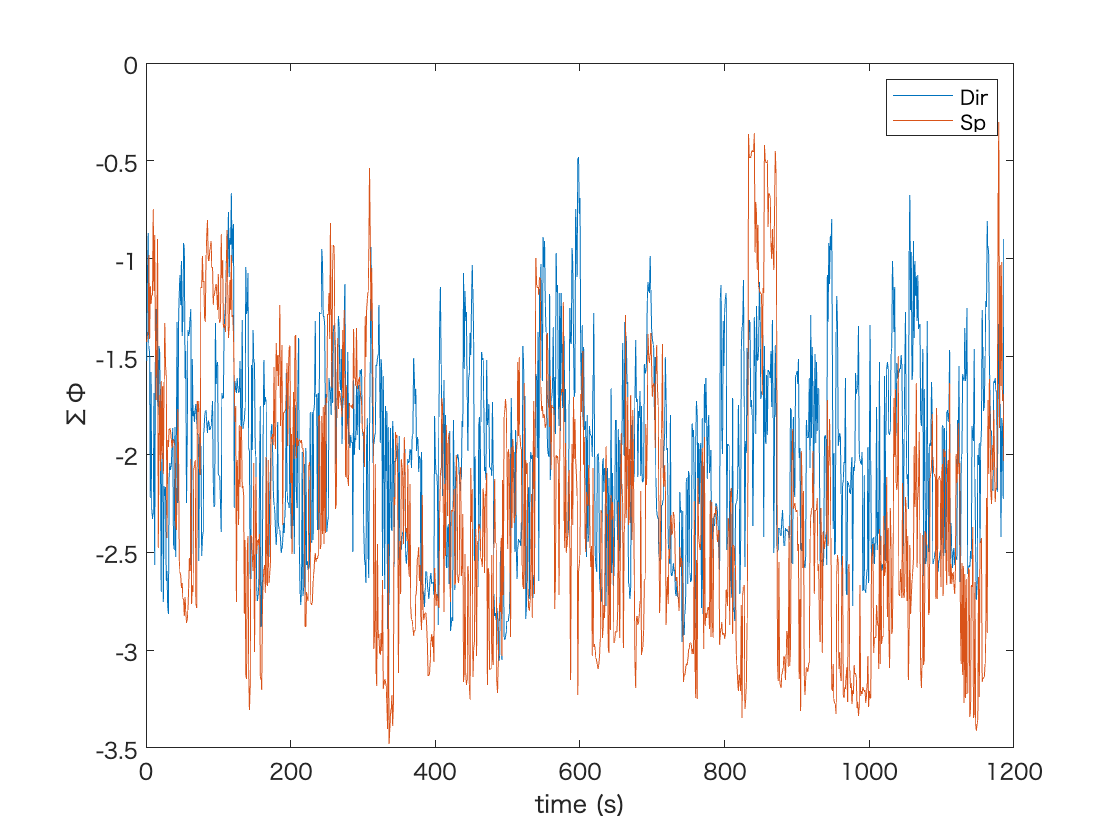

plot(log(MC_sumPHI{1, ind}(20*l:end-1))) % PHI_dir
hold on;
plot(log(MC_sumPHI{2, ind}(20*l:end-1))) % PHI_sp
hold off;

legend('Dir','Sp')
xlabel('time (s)');
ylabel('ΣΦ');

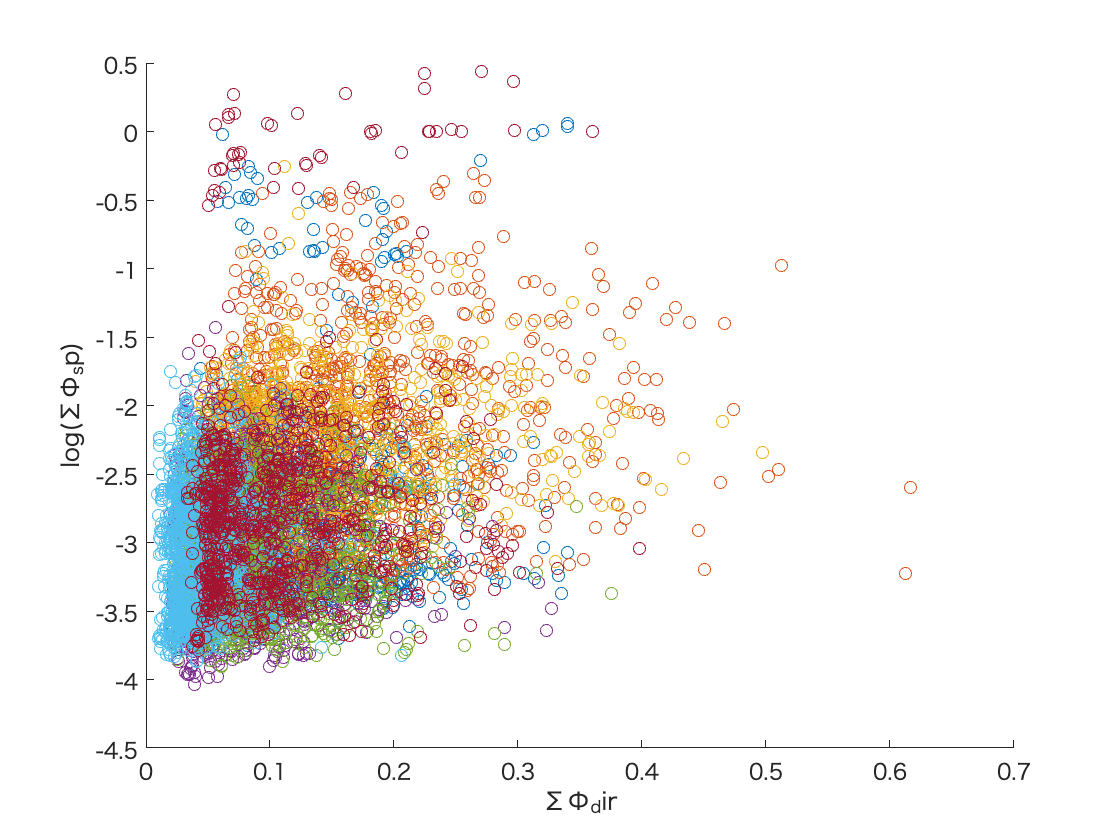


% Figure 2b
for ind = 1 : 7
    scatter((MC_sumPHI{1, ind}(20*l:end-1)), log(MC_sumPHI{2, ind}(20*l:end-1)))
    hold on
end
xlabel('ΣΦ_dir');
ylabel('log(ΣΦ_sp)');
hold off

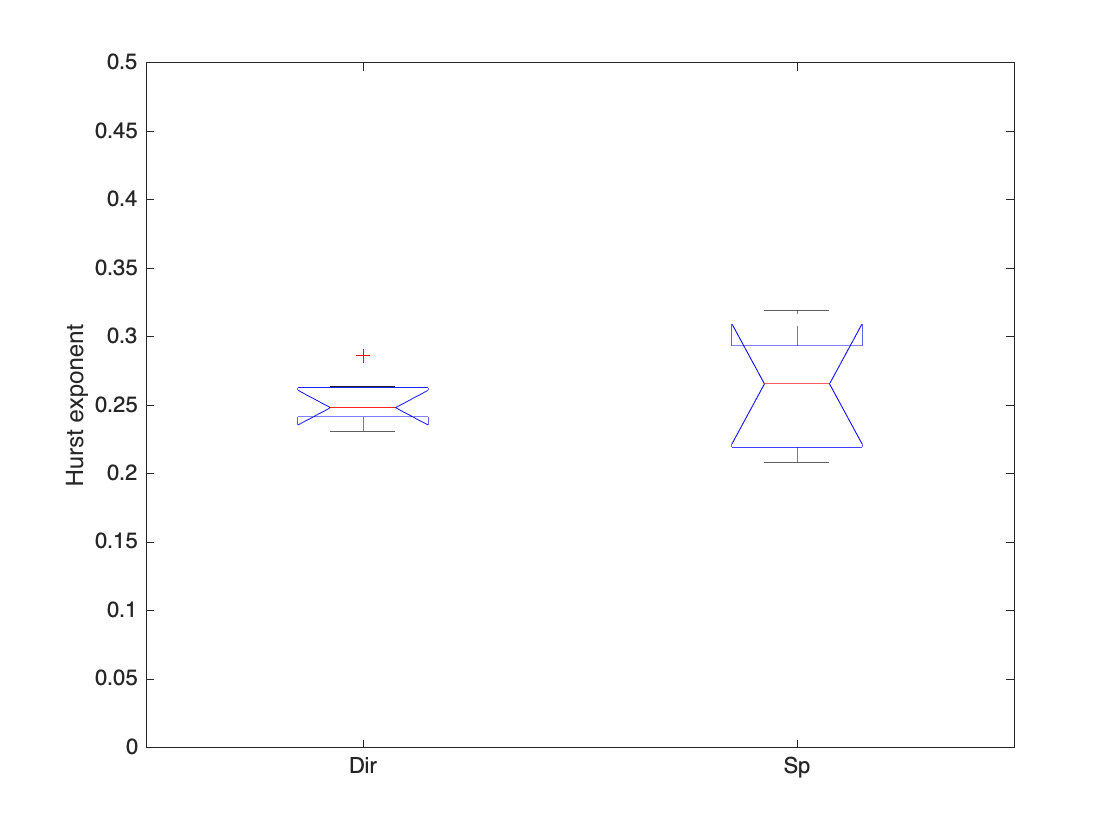

hurst_exp = zeros(7, 4);

% Hurst exp for real fish data and shuffled data
for ind = 1 :7
    hurst_exp(ind, 1) = genhurst((log(MC_sumPHI{1, ind}(20*l:end-1))));
    hurst_exp(ind, 2) = genhurst((log(MC_sumPHI{2, ind}(20*l:end-1))));
    hurst_exp(ind, 3) = genhurst(Shuffle(log(MC_sumPHI{1, ind}(20*l:end-1))));
    hurst_exp(ind, 4) = genhurst(Shuffle(log(MC_sumPHI{2, ind}(20*l:end-1))));
end

boxplot(hurst_exp(:, 1:2), 'Notch','on', 'Labels',{'Dir','Sp'},'Whisker',1)
ylabel('Hurst exponent');
ylim([0, 0.5])


% test hurst_exp with 0.5 or 0
[h,p,ci,stats] = ttest(hurst_exp(:,1), 0.5)

h = 1

p = 3.2456e-08

ci =     0.2367
    0.2705


stats = フィールドをもつ struct :
    tstat: -35.6538
       df: 6
       sd: 0.0183


[h,p,ci,stats] = ttest(hurst_exp(:,2), 0.5)

h = 1

p = 5.4048e-06

ci =     0.2198
    0.2982


stats = フィールドをもつ struct :
    tstat: -15.0588
       df: 6
       sd: 0.0423


## 1/f analysis

F_phi = zeros(2, 7);
F_sumphi = zeros(2, 7);
F_numcom = zeros(2, 7);

total_F_phi_1 = [];
total_F_phi_2 = [];
total_sumF_phi_1 = [];
total_sumF_phi_2 = [];
total_F_num_1 = [];
total_F_num_2 = [];

for ind = 1 : 7
    F_phi(1, ind) = PowerSpectrum(MC_PHI{1, ind}(20*l:end-1));
    F_phi(2, ind) = PowerSpectrum(MC_PHI{2, ind}(20*l:end-1));
    F_sumphi(1, ind) = PowerSpectrum(log(MC_sumPHI{1, ind}(20*l:end-1)));
    F_sumphi(2, ind) = PowerSpectrum(log(MC_sumPHI{2, ind}(20*l:end-1)));
    F_numcom(1, ind) = PowerSpectrum(MC_numCOM{1, ind}(20*l:end-1));
    F_numcom(2, ind) = PowerSpectrum(MC_numCOM{2, ind}(20*l:end-1));
    
    total_F_phi_1 = [total_F_phi_1; MC_PHI{1, ind}(20*l:end-1).'];
    total_F_phi_2 = [total_F_phi_2; MC_PHI{2, ind}(20*l:end-1).'];
    total_sumF_phi_1 = [total_sumF_phi_1; MC_sumPHI{1, ind}(20*l:end-1).'];
    total_sumF_phi_2 = [total_sumF_phi_2; MC_sumPHI{2, ind}(20*l:end-1).'];
    total_F_num_1 = [total_F_num_1; MC_numCOM{1, ind}(20*l:end-1).'];
    total_F_num_2 = [total_F_num_2; MC_numCOM{2, ind}(20*l:end-1).']; 
end

T = table(F_phi.',F_sumphi.',F_numcom.');
T.Properties.VariableNames{'Var1'} = 'Max_PHI (Dir/Sp)';
T.Properties.VariableNames{'Var2'} = 'sumPHI (Dir/Sp)';
T.Properties.VariableNames{'Var3'} = 'Main_Complex_Size (Dir/Sp)';
T

T = 7×3 table
     Max_PHI (Dir/Sp)       sumPHI (Dir/Sp)       Main_Complex_Size (Dir/Sp)
    __________________    ____________________    __________________________

    -1.5491    -1.6915      -0.942     -1.1911       -0.81068    -0.91223   
    -1.6676    -1.8349    -0.94735     -1.0942        -0.8807    -0.87657   
    -1.8031    -1.7228     -0.9639    -0.86901       -0.81462    -0.86128   
    -1.8672    -1.5425     -1.0179     -0.8059       -0.94637     -0.6286   
    -1.6329    -1.5598    -0.93028    -0.84083       -0.73261    -0.78426   
    -1.4188    -1.5381     -1.0447     -0.8813       -0.87114    -0.70689   
    -1.6209    -1.6712    -0.90846     -1.2962       -0.86471     -1.1104   


### Figure 3

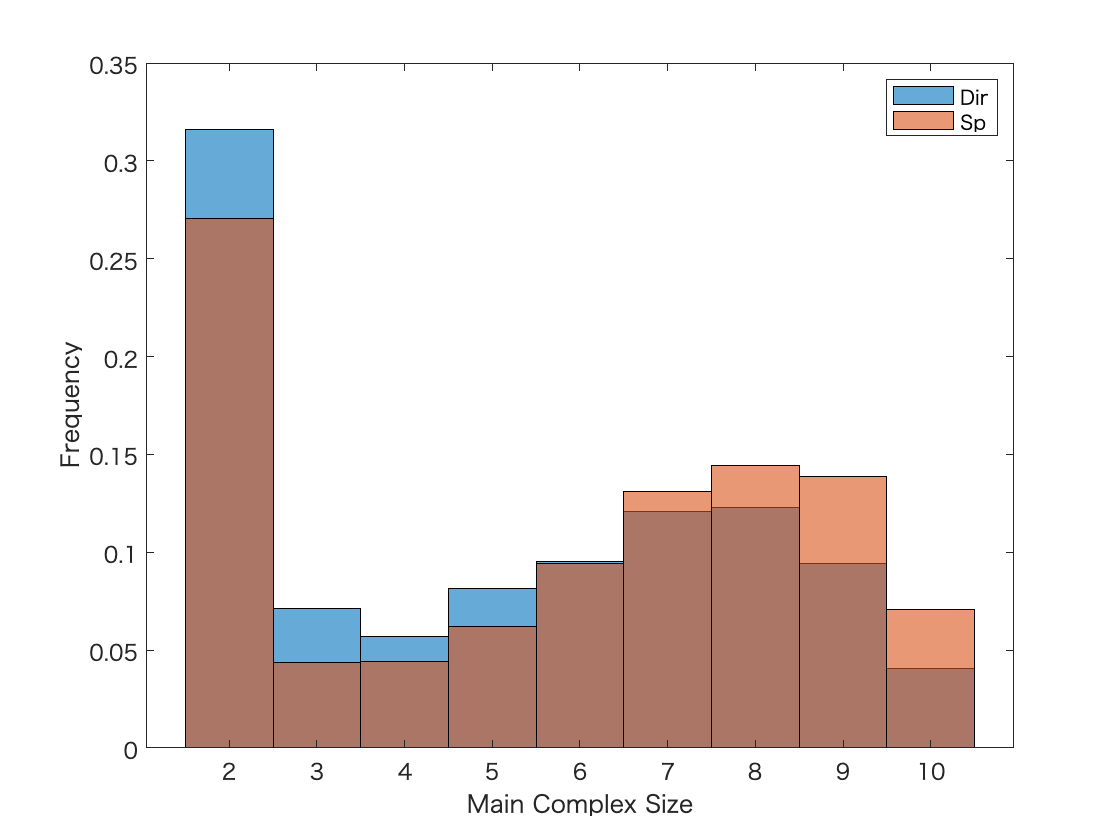

% complex size
% Figure 3a

bits = [1, 2, 4, 8, 16, 32, 64, 128, 256, 512];
complex_bits = cell(2, 7);

for ind = 1 : 7
    times = length(MC_COM{1,ind});
    cb1 = zeros(times, 10);
    cb2 = zeros(times, 10);
    for t = 1 : times
        cb1(t, :) = de2bi(MC_COM{1,ind}(t), 10);
        cb2(t, :) = de2bi(MC_COM{2,ind}(t), 10);
    end
    complex_bits{1, ind} = cb1;
    complex_bits{2, ind} = cb2;
end

total_com_size_1 = [];
total_com_size_2 = [];
index_seq = [];

for ind = 1 : 7
    com_size_1 = sum(complex_bits{1, ind}, 2);
    com_size_2 = sum(complex_bits{2, ind}, 2);
    total_com_size_1 = [total_com_size_1; com_size_1(20*l:end-1)];
    total_com_size_2 = [total_com_size_2; com_size_2(20*l:end-1)];
    
    N = size(com_size_1(20*l:end-1), 1);
    index_seq = [index_seq; repmat(ind,  [N, 1])];
end

h = histogram(total_com_size_1, "Normalization","probability");
hold on 
h = histogram(total_com_size_2, "Normalization","probability");
hold off
legend('Dir','Sp')
xlabel('Main Complex Size');
ylabel('Frequency');

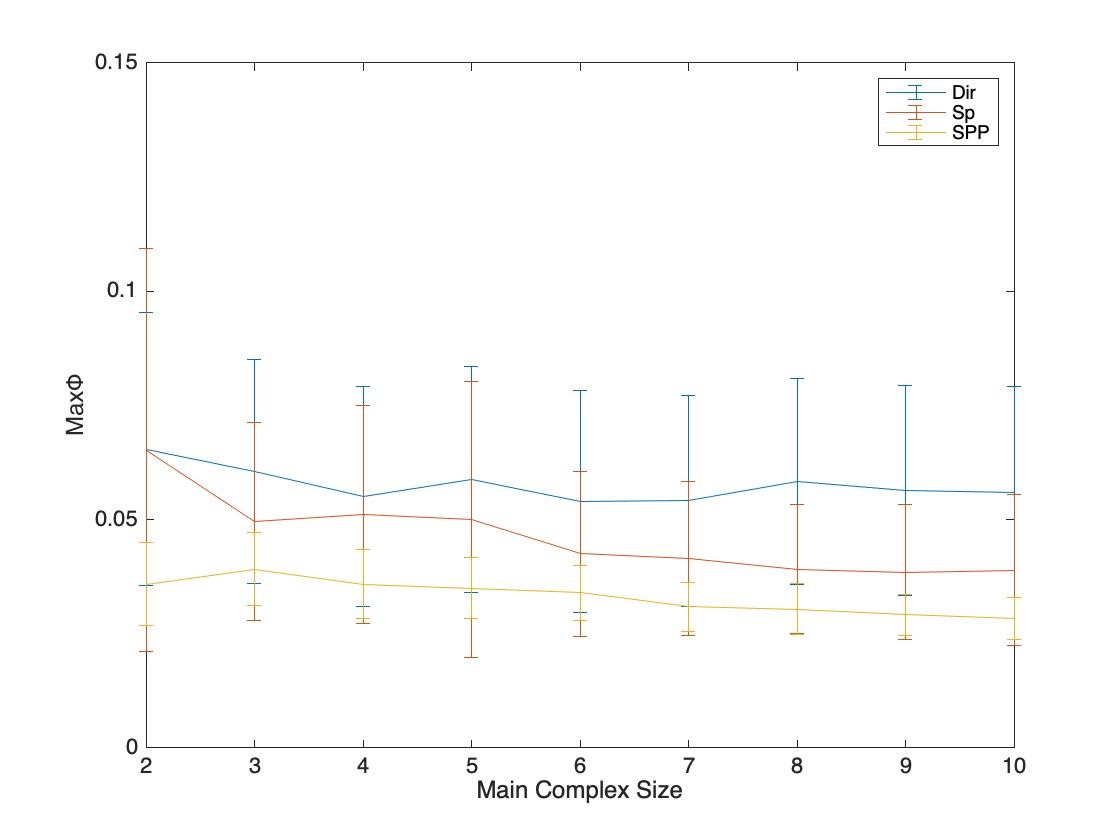

% Figure 3b
mean_phi = zeros(9, 2);
std_phi = zeros(9, 2);
spp_phi = readmatrix("peak_MIP.csv");

for s = 2: 10
    ids = find(spp_phi(:, 1) == s);
    mean_phi(s-1, 1) = mean(total_F_phi_1(total_com_size_1 == s));
    mean_phi(s-1, 2) = mean(total_F_phi_2(total_com_size_2 == s));
    mean_phi(s-1, 3) = mean(spp_phi(ids, 2));
    std_phi(s-1, 1) = std(total_F_phi_1(total_com_size_1 == s));
    std_phi(s-1, 2) = std(total_F_phi_2(total_com_size_2 == s));
    std_phi(s-1, 3) = std(spp_phi(ids, 2));
end

errorbar(2:10, mean_phi, std_phi)
legend('Dir','Sp', 'SPP')
ylabel('Max{Φ}');
xlabel('Main Complex Size');
ylim([0, 0.15])

### Figure 4

Fish_analysis;
p_int = (1:20) * 0.05;
m_int = (1:20) * 0.05;

phi_cells = zeros(400, 3);
phi_cells2 = zeros(400, 3);
Phi_dir =[];
Phi_sp = [];
P=[];
M=[];

for ind = 1 : 7
    Phi_dir = [Phi_dir, log(MC_PHI{1, ind}(20*l:end-1))];
    Phi_sp = [Phi_sp, log(MC_PHI{2, ind}(20*l:end-1))];
    P = [P, LPP{1, ind}(20*l:end-1)];
    M = [M, LMM{1, ind}(20*l:end-1)];
end

for i = 1:20
    for j = 1:20
            a = p_int(i) - 0.05;
            b = p_int(i);
            c = m_int(j) - 0.05;
            d = m_int(j);
            I = find((P>a) & (P<b) & (M>c) & (M<d));
            phi_cells(j + (i-1)*20, 1) = b;
            phi_cells(j + (i-1)*20, 2) = d;
            phi_cells2(j + (i-1)*20, 1) = b;
            phi_cells2(j + (i-1)*20, 2) = d;

            if ~isempty(I)
                phi_cells(j + (i-1)*20, 3) = phi_cells(i + (j-1)*10, 3)+ mean(Phi_dir(I));
                phi_cells2(j + (i-1)*20, 3) = phi_cells2(i + (j-1)*10, 3)+ mean(Phi_sp(I));
            end
     end
end


phi_cells(phi_cells==0) = -inf;
phi_cells2(phi_cells2==0) = -inf;

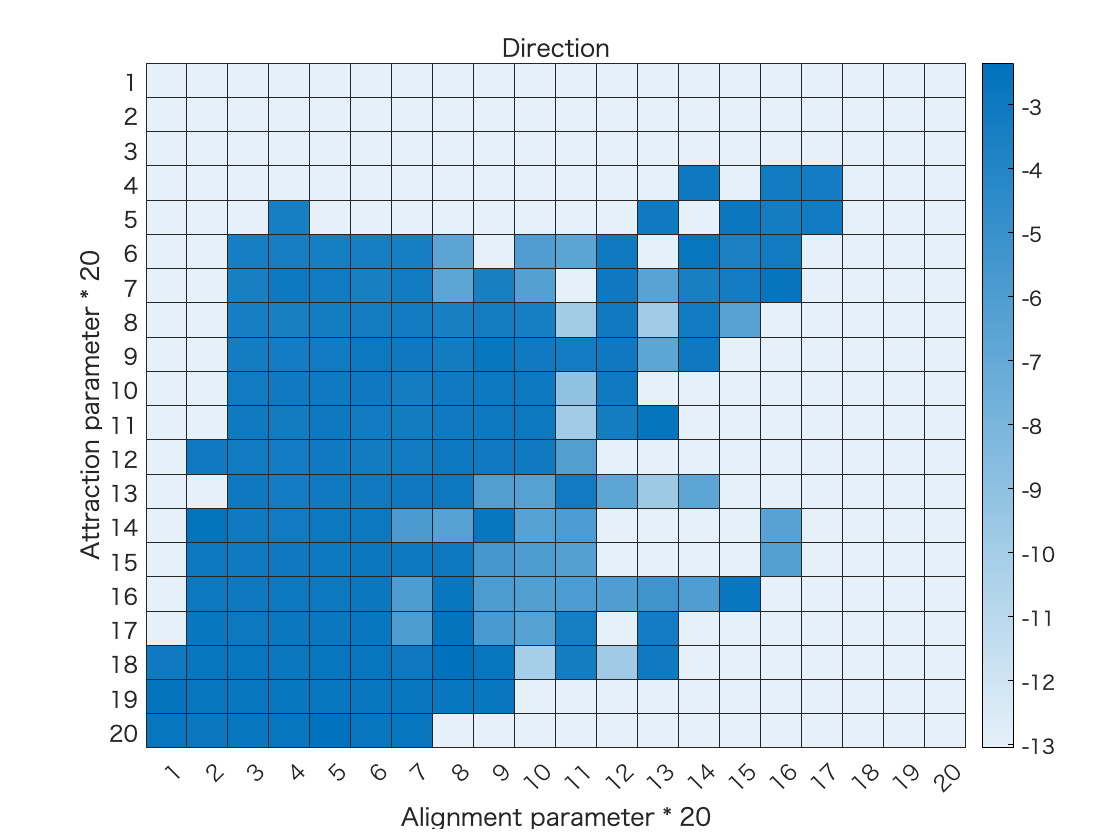

cell_dir = zeros(20, 20);
cell_sp = zeros(20, 20);

for i = 1 :20
    for j = 1:20
        cell_dir(i, j) = phi_cells(j + (i-1)*20, 3);
        cell_sp(i, j) = phi_cells2(j + (i-1)*20, 3);
    end
end

heatmap(cell_dir)
title("Direction")
xlabel('Alignment parameter * 20');
ylabel('Attraction parameter * 20');

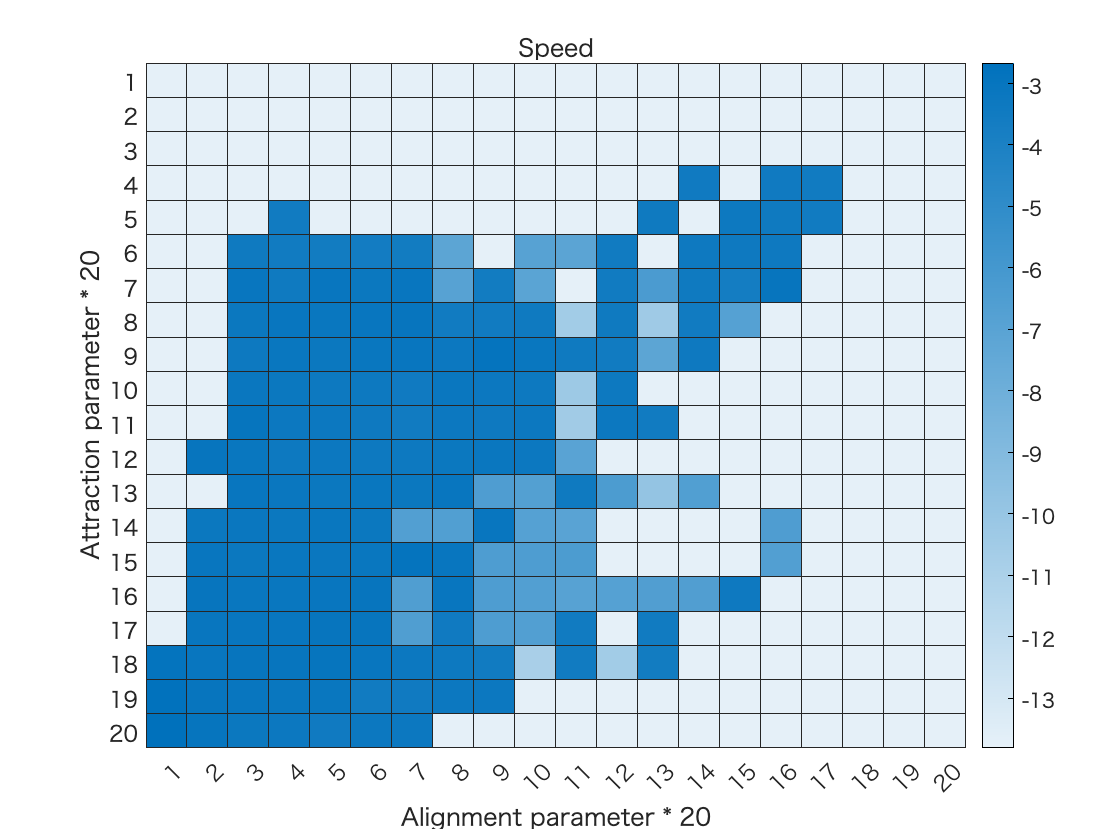


heatmap(cell_sp)
title("Speed")
xlabel('Alignment parameter * 20');
ylabel('Attraction parameter * 20');

### **Figure 5**

%% 寿命の測定
lifespan_cum = zeros(7, 500);
lifespan = zeros(7, 500);
lifespan_all = zeros(1, 500);
lifespan_cum_all = zeros(1, 500);
Sq = zeros(7, 500);

for ind = 1 : 7
    test = complex_bits{1, ind}(20*l:end-1, :);
    for n = 1 : 10
        one_test = test(: ,n);
        index = find(one_test==0);
        result = index-circshift(index, 1)-1;
        result = result(result>0);

        for t = 1 : length(result)
            lifespan(ind, result(t)) = lifespan(ind, result(t)) + 1;
            lifespan_all(result(t)) = lifespan_all(result(t)) + 1;
        end
    end

    for t = 1 :500
        lifespan_cum(ind, t) = sum(lifespan(ind, t:end));
        lifespan_cum_all(t) = sum(lifespan_all(t:end));
        Sq(ind, t) = 1 - sum(lifespan(ind, 1:t-1))/sum(lifespan(ind, 1:end));
    end
    
end

% ワイブル分布（stretched exponential) direction
% 単語シャッフルに類似したもの
W_theta = zeros(2, 7);
W_kappa = zeros(2, 7);
W_test = zeros(2, 7);
WS_theta = zeros(2, 7);
WS_kappa = zeros(2, 7);
WS_test = zeros(2, 7);
type = 1;
shuffle_data;

for ind = 1: 7
    x0 = [0, 0]; 
    new_lamda = sum((1:500).*lifespan(ind, :))/sum(lifespan(ind, :));
    fitfun = fittype( @(theta,k, x) exp(-k*(x/new_lamda).^theta));
    Sq_sample = Sq(ind, :);
    L = length(Sq_sample(Sq_sample>0));
    [fitted_curve,gof] = fit((0:L-1).',Sq(ind, 1:L).',fitfun,'StartPoint',x0);
    coeffvals = coeffvalues(fitted_curve);
    W_theta(1, ind) = coeffvals(1);
    W_kappa(1, ind) = coeffvals(2);
    W_test(1, ind) = gof.sse;
 
    x0 = [0, 0]; 
    fitfun = fittype( @(theta,k, x) exp(-k*(x/lamda(ind)).^theta));
    [fitted_curve,gof] = fit((0:L-1).',Sq_shuffle(ind, 1:L).',fitfun,'StartPoint',x0);
    coeffvals = coeffvalues(fitted_curve);
    WS_theta(1, ind) = coeffvals(1);
    WS_kappa(1, ind) = coeffvals(2);
    WS_test(1, ind) = gof.sse;
end

Sq_shuffle_dir = Sq_shuffle;

%% speed
lifespan_cum = zeros(7, 500);
lifespan = zeros(7, 500);
lifespan_all = zeros(1, 500);
lifespan_cum_all = zeros(1, 500);
Sq_2 = zeros(7, 500);

for ind = 1 : 7
    test = complex_bits{2, ind}(20*l:end-1, :);
    for n = 1 : 10
        one_test = test(: ,n);
        index = find(one_test==0);
        result = index-circshift(index, 1)-1;
        result = result(result>0);

        for t = 1 : length(result)
            lifespan(ind, result(t)) = lifespan(ind, result(t)) + 1;
            lifespan_all(result(t)) = lifespan_all(result(t)) + 1;
        end
    end

    for t = 1 :500
        lifespan_cum(ind, t) = sum(lifespan(ind, t:end));
        lifespan_cum_all(t) = sum(lifespan_all(t:end));
        Sq_2(ind, t) = 1 - sum(lifespan(ind, 1:t-1))/sum(lifespan(ind, 1:end));
    end
    
end

% ワイブル分布（stretched exponential) direction
% 単語シャッフルに類似したもの

type = 2;
shuffle_data;

for ind = 1: 7
    x0 = [0, 0]; 
    new_lamda = sum((1:500).*lifespan(ind, :))/sum(lifespan(ind, :));
    fitfun = fittype( @(theta,k, x) exp(-k*(x/new_lamda).^theta));
    Sq_sample = Sq_2(ind, :);
    L = length(Sq_sample(Sq_sample>0));
    [fitted_curve,gof] = fit((0:L-1).',Sq_2(ind, 1:L).',fitfun,'StartPoint',x0);
    coeffvals = coeffvalues(fitted_curve);
    W_theta(2, ind) = coeffvals(1);
    W_kappa(2, ind) = coeffvals(2);
    W_test(2, ind) = gof.sse;
 
    x0 = [0, 0]; 
    fitfun = fittype( @(theta,k, x) exp(-k*(x/lamda(ind)).^theta));
    [fitted_curve,gof] = fit((0:L-1).',Sq_shuffle(ind, 1:L).',fitfun,'StartPoint',x0);
    coeffvals = coeffvalues(fitted_curve);
    WS_theta(2, ind) = coeffvals(1);
    WS_kappa(2, ind) = coeffvals(2);
    WS_test(2, ind) = gof.sse;
end

Sq_shuffle_sp = Sq_shuffle;

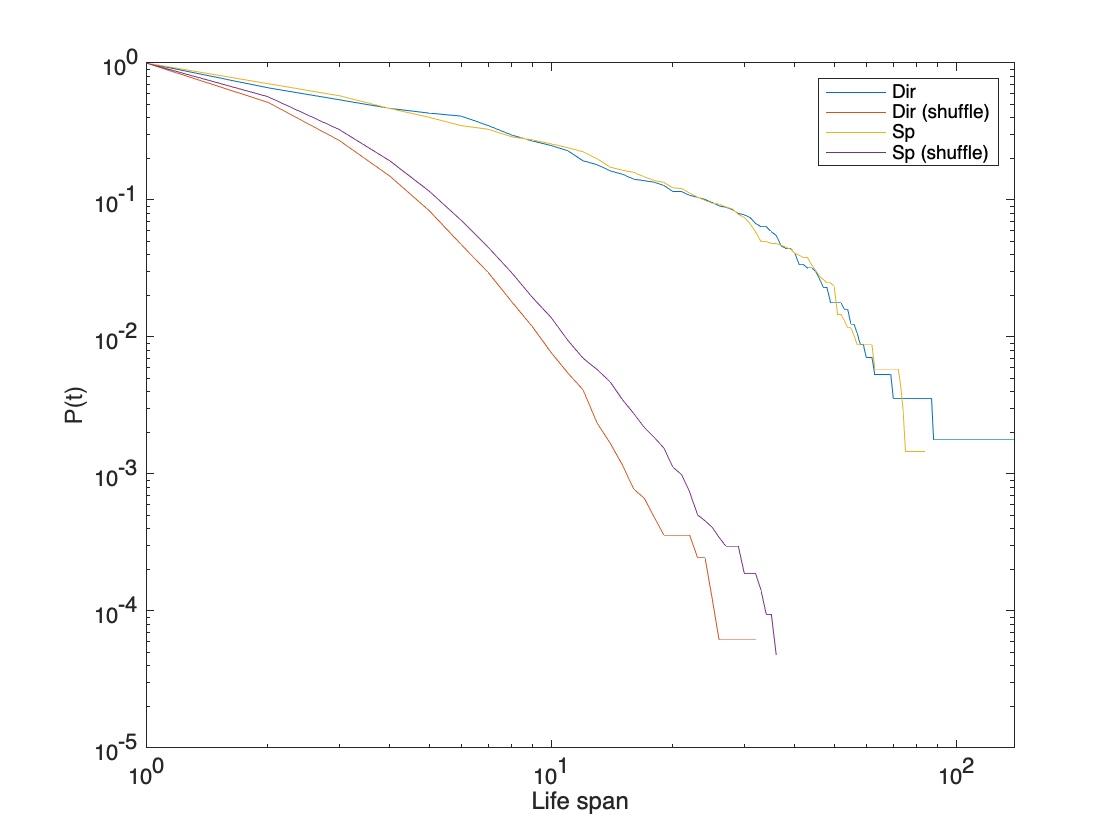

S = [Sq(1, :).', mean(Sq_shuffle_dir).'];
S2 = [Sq_2(1, :).', mean(Sq_shuffle_sp).'];
loglog(S)
hold on;
loglog(S2)
legend('Dir', 'Dir (shuffle)','Sp', 'Sp (shuffle)')
xlabel('Life span');
ylabel('P(t)');
hold off


%% Weibull_compared for all cases

[WS_theta,WS_kappa,WS_lamda, LS_sample, Sq_shuffle_sample] = Weibul_shufflle(complex_bits, l, 1);

T = table(W_theta.', W_kappa.', WS_theta.', WS_kappa.');
T.Properties.VariableNames{'Var1'} = 'theta';
T.Properties.VariableNames{'Var2'} = 'kappa';
T.Properties.VariableNames{'Var3'} = 'theta(control)';
T.Properties.VariableNames{'Var4'} = 'kappa(control)';

T

T = 7×4 table
          theta                kappa          theta(control)    kappa(control)
    __________________    ________________    ______________    ______________

    0.57707      0.583    1.3345    1.3187       0.93405            1.3807    
    0.59622    0.62764    1.3043    1.2941       0.94913            1.0246    
    0.57007    0.61711    1.3342    1.3009       0.92622           0.86325    
    0.62183     0.6019    1.3048    1.2827       0.96374             1.792    
    0.64412    0.59351    1.2898    1.3375       0.96793            1.7641    
    0.57319    0.59437    1.3417    1.3023       0.98113            1.3058    
    0.66057    0.63132    1.2415    1.3238       0.98477           0.95068    


### Figure 6

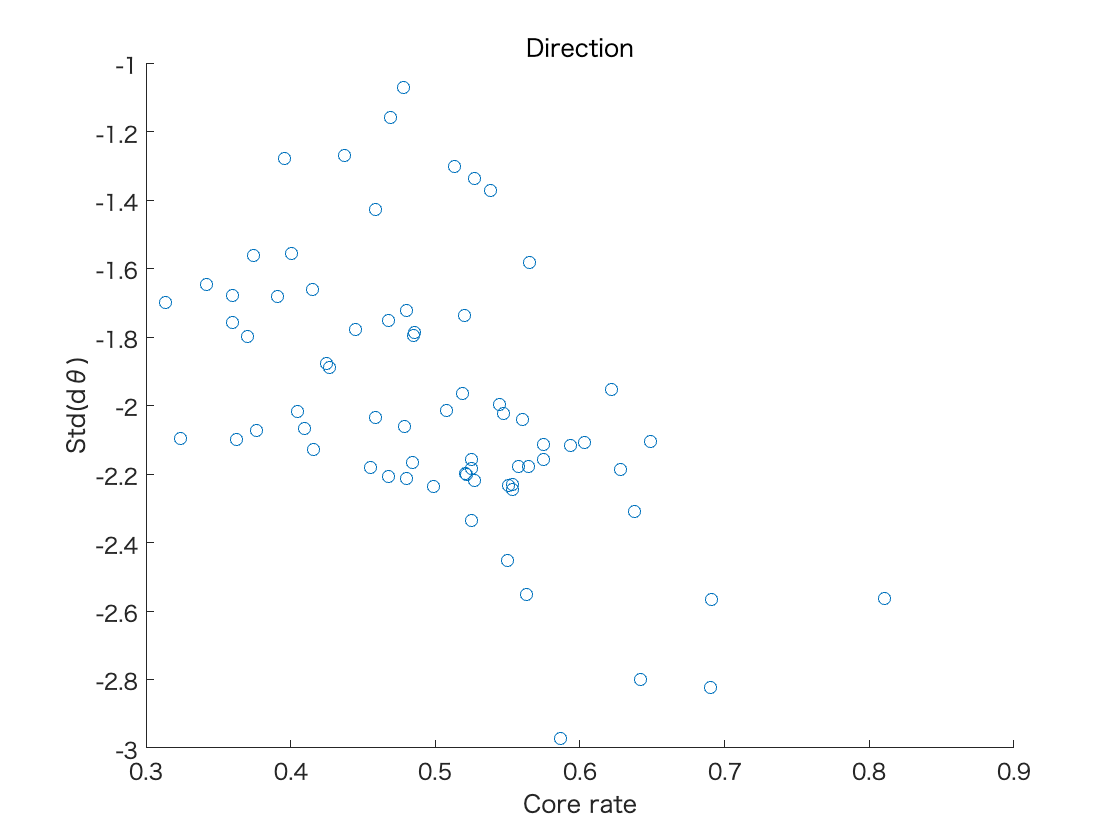

data_import;
a = [];
b = [];

for ind = 1:7
    n = size(complex_bits{1,ind}, 1);
    a = [a, sum(complex_bits{1,ind}/n)];
    b = [b, log(std(dshita{ind}))];
end

c = [];
d = [];
for ind = 1:7
    n = size(complex_bits{2,ind}, 1);
    c = [c, sum(complex_bits{2,ind}/n)];    
    d = [d, log(std(accel{ind} + 0.0001))];
end

scatter(a,b)
ylabel('Std(dθ)');
xlabel('Core rate');
title("Direction")


[cor, p] = corr(a.',b.')

cor = -0.5362

p = 1.7205e-06

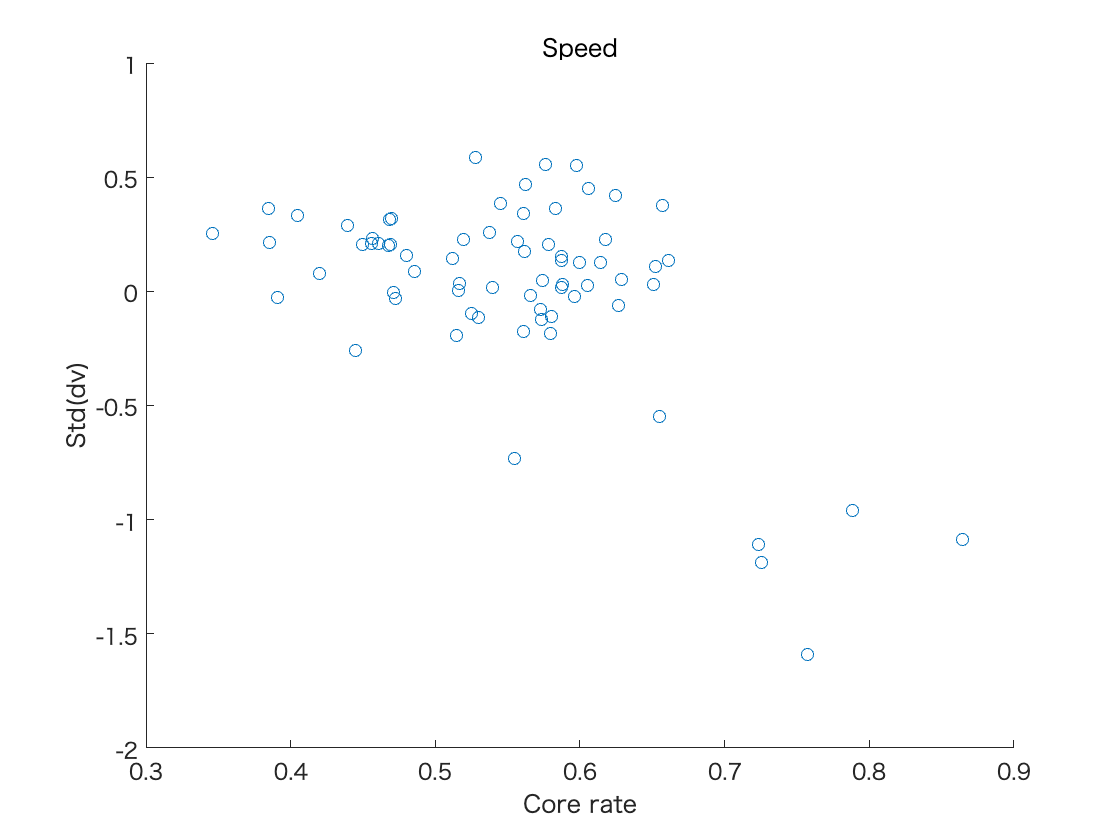


scatter(c,d)
ylabel('Std(dv)');
xlabel('Core rate');
title("Speed")


[cor, p] = corr(c.',d.')

cor = -0.5652

p = 3.4413e-07